Sistema  de Control II -FCEFyN-UNC 

Prof: Dr. Ing. Pucheta, Julian 

Alumna: Gonzalez, Macarena 

clc; clear all; close all;
%%
% PARÁMETROS DEL MOTOR
% Parámetros ajustados de acuerdo al torque

Ei =2;                    % tensión aplicada

Ra=2.4136

Ra = 2.4136

La=0.005026

La = 0.0050

Ki=0.2774

Ki = 0.2774

Bm=0

Bm = 0

Jm=0.0034

Jm = 0.0034

Km=0.2625

Km = 0.2625

%%
% MODELADO DEL MOTOR EN EL ESPACIO DE ESTADOS

% Variables de estado
% x1 = ia, x2 = wr, x3 = theta
% Salidas
% y1 = wr
% Entradas
% u1 = Ei, u2 = TL
As = [-Ra/La -Km/La 0 ; Ki/Jm -Bm/Jm 0 ; 0 1 0]; % matriz de estados      
Bs = [1/La 0 ; 0 -1/Jm ; 0 0];                   % matriz de entrada
Cs = [0 1 0];                                    % matriz de salida
Ds = [0 0];                                      % matriz de transmisión directa

% Condiciones iniciales y punto de operación
ia(1)    = 0;
wr(1)    = 0;
theta(1) = 0;
acc(1)   = 0;
x        = [ia(1) wr(1) theta(1)]';             % vector variables de estado
xop      = [0 0 0]';                            % punto de operación
wr_ref   = 1;                                   % consigna

% Funciones de transferencia del sistema
% Wr(s)/Ei(s)
[num1 den1] = ss2tf(As,Bs,Cs,Ds,1);
G_w_e       = tf(num1,den1);
% Wr(s)/TL(s)
[num2 den2] = ss2tf(As,Bs,Cs,Ds,2);
G_w_tl      = tf(num2,den2);

%%
% PARÁMETROS DE SIMULACIÓN
poles  = pole(G_w_e);                           % se calculan los polos para obtener la dinámica rápida del sistema
tR     = log(0.95)/real(poles(2));              % dinámica rápida
Ts     = tR/2;                                  % se calcula el tiempo de muestreo << tR
tF     = 0.6;                                   % tiempo final de simulación
t      = 0:Ts:tF;                               % vector de tiempo para las gráficas
tL     = zeros(1, length(t));                   % vector de torque
TL     = 0.12;                               % acción de torque

for i=1:tF/Ts
    t_ = t(i);
 
    if (((0.1869<=t_) && (t_<0.3372)) || t_>=0.4872)
        tL(i) = TL;
    else
        tL(i) = 0;
    end
end

e = zeros(1,length(t));         % vector de error
%u = zeros(1,length(t));         % vector acción de control PID
u = 0;
%%
% PID discreto
% u(i+1) = u(i) + A*e(i) + B*e(i-1) + C*e(i-2)

% Parámetros PID
Kp = 110; Ki =10; Kd = 0;
%Kp = 0.1; Ki = 0.01; Kd = 5;
A  = ((2*Kp*Ts)+(Ki*(Ts^2))+(2*Kd))/(2*Ts); 
B  = (-2*Kp*Ts+Ki*(Ts^2)-4*Kd)/(2*Ts); 
C  = Kd/Ts;

for i=1 : tF/Ts
    e(i) = wr_ref - theta(i);
    
    % Aplicación del PID discreto 
    if i==1
        u = u + A*e(i);
    end
    if i==2
        u = u + A*e(i) + B*e(i-1);
    end
    if i>2
        u = u + A*e(i) + B*e(i-1) + C*e(i-2);
    end
    
    xp = As*x + Bs*[u tL(i)]';
    x  = x + xp*Ts;                      % método de Euler
    
    ia(i+1)    = x(1);
    wr(i+1)    = Cs*x;
    theta(i+1) = x(3);
    acc(i+1)   = u;
end

%%
% GRÁFICAS

figure(1)
subplot(4,1,1)
plot(t, wr, 'k'); grid; hold on;
title('\omega_r [Rad/s]'); xlabel('Tiempo [s]'); ylabel('\omega_r [Rad/s]'); ylim([-10 10]);
subplot(4,1,2)
plot(t, ia, 'k'); grid; hold on;
title('Corriente [A]'); xlabel('Tiempo [s]'); ylabel('Corriente [A]'); ylim([0 0.1]); grid;
subplot(4,1,3)
plot(t, theta, 'k'); grid; hold on;
title('\Theta [Rad]');xlabel('Tiempo [s]'); ylabel('\Theta [Rad]'); ylim([0 2]); grid;
subplot(4,1,4)
plot(t, tL, 'k'); grid; hold on;
title('Entradas'); xlabel('Tiempo [s]'); ylabel('[N.m]'); legend('Torque')

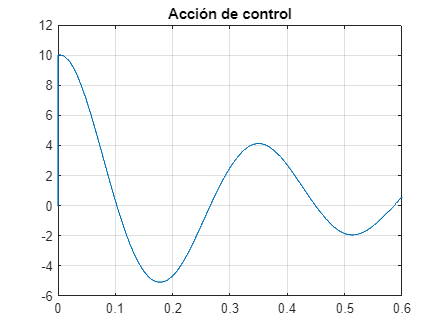


%%
figure(2)
plot(t,acc); grid; hold on;
title('Acción de control');